clc
clear
load("MatlabData/trainingData_OG.mat")
trainingData(:,12) = [];
trainingData(:,11) = [];
trainingData(:,2) = [];
D = 2;

Calculate the covariance matrix

sigma = cov(trainingData);

Calculate the EVD and sort in descending order

[V, e] = eig(sigma);
[e_sort, I] = sort(diag(e),'descend');

Plot the histogram

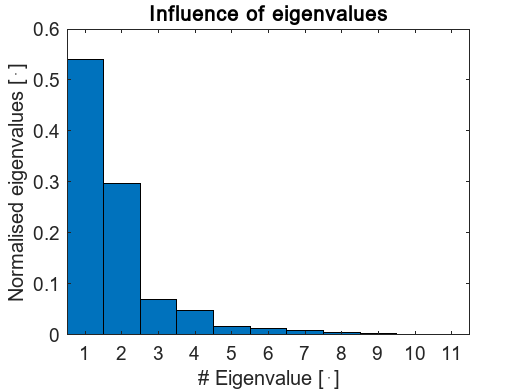

bar(linspace(1,11,11),e_sort/sum(e_sort),1)
xlim([0.5,11.5])
title('Influence of eigenvalues')
xlabel('# Eigenvalue [⋅]')
ylabel('Normalised eigenvalues [⋅]')

saveas(gcf,'Images/PCA_bar','epsc')


e_12 = (e_sort(1) + e_sort(2)) / sum(e_sort)

e_12 = 0.8377

Construct W

W = zeros(11, D);
for i=1:D
    W(:,i) = V(I(i),:)';
end

Print W

W

W =     0.0003    0.0002
   -0.0001    0.0003
   -0.0355   -0.4924
   -0.0279   -0.1472
    0.0034    0.2727
    0.0147    0.5263
   -0.0231   -0.5953
   -0.9968    0.0356
    0.0562   -0.1007
    0.0203   -0.1357
